# Assignment 7 Exercise 2

Part a

P0 = 120;
aP = 3e-4;
aN = 7e-4;

P = @(q) P0 - aP*q.^2;
N = @(q) aN*q.^2;


Part b

q = linspace(0, 500);
plot(q, P(q))
hold on
plot(q, N(q))


Part c

F = @(q) P(q)-N(q);
q0_1 = fsolve(F, 1) % 346 Good Approximation


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


q0_1 = 346.4102

q0_0 = fsolve(F, 0) % Failed to solve


No solution found.

fsolve stopped because the problem appears regular as measured by the gradient,
but the vector of function values is not near zero as measured by the
value of the function tolerance.

<stopping criteria details>


q0_0 = 0

q0_n1 = fsolve(F, -1) % -346 Bad Approximation


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


q0_n1 = -346.4102

% The -1 and 1 approximations are accurate because they both find minima.
% The -1 finds one to the left, and the 1 find one to the right.
% The 0 approximation, however, failed because it is equidistant from both
% minima.

Part d

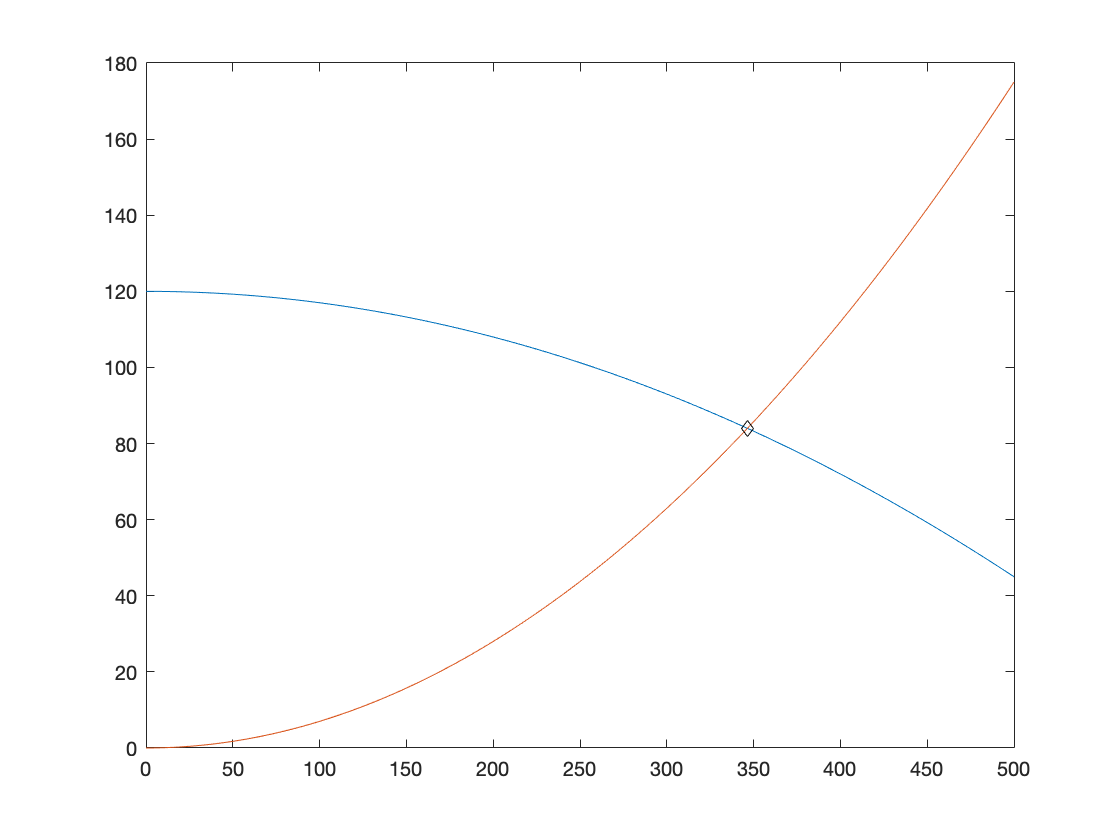

plot(q0_1, P(q0_1), 'kd')